# 4.9 Discrete controller and observer

% select the sampling time
fSamplingPeriod = 0.005;

load poles.mat
load Linear_Param.mat
poles

poles =   -6.6476e+02 + 0.0000e+00i
  -5.0809e+00 + 0.0000e+00i
  -2.4802e+00 + 3.5205e-01i
  -2.4802e+00 - 3.5205e-01i


A;
B = B(:,1);
C = [1 0 0 0;
    0 0 1 0];
D = 0;
contStateSpace = ss(A,B,C,D)

contStateSpace =
 
  A = 
           x1      x2      x3      x4
   x1       0       1       0       0
   x2       0    -435  -6.099   9.136
   x3       0       0       0       1
   x4       0    1903   62.02  -39.97
 
  B = 
           u1
   x1       0
   x2   20.58
   x3       0
   x4  -90.03
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   0   1   0
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.



discreteStateSpace = c2d(contStateSpace,fSamplingPeriod);
Ad = discreteStateSpace.A

Ad =    1.0000e+00   2.1694e-03  -3.5615e-05   5.9372e-05
            0   1.6926e-01  -9.5490e-03   1.7410e-02
            0   1.2386e-02   1.0006e+00   4.7409e-03
            0   3.6357e+00   2.1849e-01   9.2425e-01


Bd = discreteStateSpace.B

Bd =    1.3388e-04
   3.9292e-02
  -5.8583e-04
  -1.7196e-01


Cd = discreteStateSpace.C

Cd =      1     0     0     0
     0     0     1     0


D = discreteStateSpace.D

D =      0
     0


discretePoles = exp(poles*fSamplingPeriod)

discretePoles =    3.6016e-02 + 0.0000e+00i
   9.7492e-01 + 0.0000e+00i
   9.8767e-01 + 1.7386e-03i
   9.8767e-01 - 1.7386e-03i



%Plotting discrete poles
scatter(real(discretePoles),imag(discretePoles))
hold on
r = 1

r =      1


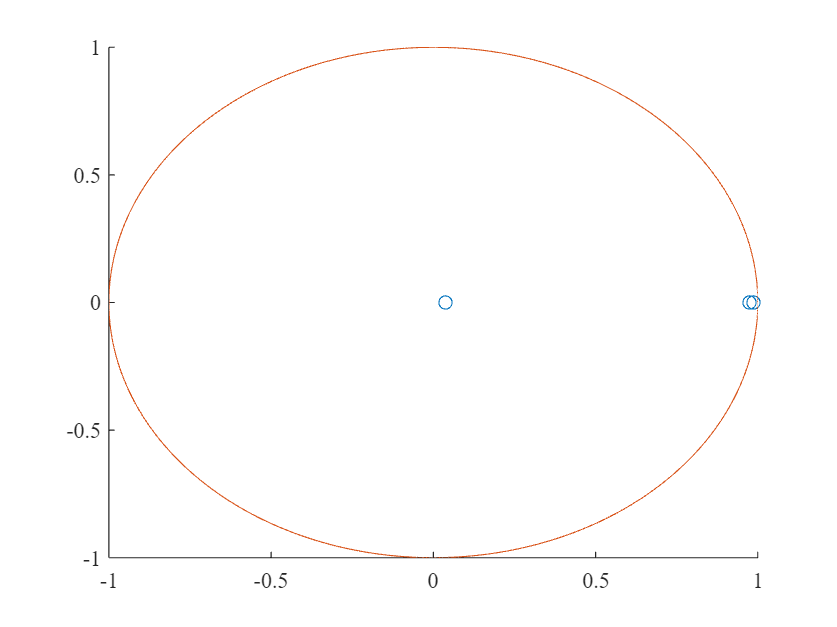

ang=0:0.01:2*pi; 
xp=r*cos(ang);
yp=r*sin(ang);
plot(xp,yp);
hold off

Controller

%State-feedback gain
Kd = place(Ad,Bd,discretePoles)

Kd =   -2.1591e+01  -4.2552e+01  -6.1688e+01  -1.0157e+01


vpa(sym(Kd),5)

$$ans = \left(\begin{array}{cccc} -21.591 & -42.552 & -61.688 & -10.157 \end{array}\right)$$

eig(Ad-Bd*Kd)

ans =    3.6016e-02 + 0.0000e+00i
   9.7492e-01 + 0.0000e+00i
   9.8767e-01 + 1.7386e-03i
   9.8767e-01 - 1.7386e-03i


Full-state observer

factor = 4;
speed = max(abs(poles(2:4)));
contObserverPoles(1) = poles(1);
contObserverPoles(2) = -2*factor*speed; % Place pole to not disturb dominant poles
omegan = factor*speed;
zeta = 0.99;
contObserverPoles(3:4) =    [omegan*(-zeta+1i*sqrt(1-zeta^2));
                             omegan*(-zeta-1i*sqrt(1-zeta^2))];
desiredPoles = exp(contObserverPoles*fSamplingPeriod)

desiredPoles =    3.6016e-02 + 0.0000e+00i   8.1608e-01 + 0.0000e+00i   9.0420e-01 + 1.2963e-02i   9.0420e-01 - 1.2963e-02i


Ld = (place(Ad',Cd',desiredPoles))'

Ld =    1.1348e-01   5.2305e-03
  -1.3682e+00   4.3732e+00
   2.3679e-02   3.2012e-01
   6.3909e+00  -1.5266e+01


vpa(sym(Ld),5)

$$ans = \left(\begin{array}{cc} 0.11348 & 0.0052305\\ -1.3682 & 4.3732\\ 0.023679 & 0.32012\\ 6.3909 & -15.266 \end{array}\right)$$

eig(Ad-Ld*Cd)

ans =    3.6016e-02 + 0.0000e+00i
   8.1608e-01 + 0.0000e+00i
   9.0420e-01 + 1.2963e-02i
   9.0420e-01 - 1.2963e-02i


Reduced order observer

T = inv([C;0 1 0 0; 0 0 0 1])

T =      1     0     0     0
     0     0     1     0
     0     1     0     0
     0     0     0     1


An = inv(T)*Ad*T ;  %New A-matrix
Bn = inv(T)*Bd;     %New B-matrix
Cbacc = Cd(1,:)*T;  %Accurate
Cbnacc = Cd(2,:)*T; %Not accurate

Ayy = An(1,1); %Zero
Ayx = An(1,2:4);  %Noisy/unobserved states
Axy = An(2:4,1); % Zero
Axx = An(2:4,2:4); %Noisy/unobserved states

By = Bn(1);
Bx = Bn(2:4);

Cy = Cbnacc(1);
Cx = Cbnacc(2:4);

AA = Axx;
CC = [Ayx
      Cx];
Lpartial = ( place( AA', CC', desiredPoles(2:4) ) )';
Lacc = Lpartial(:,1);
Lnacc = Lpartial(:,2);

poles(2:4);
observerPoles = eig(AA-Lpartial*CC)

observerPoles =    8.1608e-01 + 0.0000e+00i
   9.0420e-01 + 1.2963e-02i
   9.0420e-01 - 1.2963e-02i



M1d = Axx-Lacc*Ayx-Lnacc*Cx

M1d =    8.1866e-01   2.0546e-02   4.9643e-03
   2.1297e-02   9.8602e-01   3.9763e-02
  -2.2469e-02  -1.8053e-01   8.1981e-01


vpa(sym(M1d),5)

$$ans = \left(\begin{array}{ccc} 0.81866 & 0.020546 & 0.0049643\\ 0.021297 & 0.98602 & 0.039763\\ -0.022469 & -0.18053 & 0.81981 \end{array}\right)$$

M2d = Bx-Lacc*By

M2d =   -8.2272e-05
   8.9697e-02
  -4.0747e-01


vpa(sym(M2d),5)

$$ans = \left(\begin{array}{c} -0.000082272\\ 0.089697\\ -0.40747 \end{array}\right)$$

M3d = Axy-Lacc*Ayy-Lnacc*Cy

M3d =    3.7613e+00
   3.7650e+02
  -1.7591e+03


vpa(sym(M3d),5)

$$ans = \left(\begin{array}{c} 3.7613\\ 376.5\\ -1759.1 \end{array}\right)$$

M4d = Lnacc

M4d =    1.8180e-01
  -4.4255e-02
   3.0360e-01


vpa(sym(M4d),5)

$$ans = \left(\begin{array}{c} 0.1818\\ -0.044255\\ 0.3036 \end{array}\right)$$

M5d = Lacc

M5d =   -3.7613e+00
  -3.7650e+02
   1.7591e+03


vpa(sym(M5d),5)

$$ans = \left(\begin{array}{c} -3.7613\\ -376.5\\ 1759.1 \end{array}\right)$$

M6d = T(:,1)

M6d =      1
     0
     0
     0


vpa(sym(M6d),5)

$$ans = \left(\begin{array}{c} 1.0\\ 0\\ 0\\ 0 \end{array}\right)$$

M7d = T(:,2:4)

M7d =      0     0     0
     0     1     0
     1     0     0
     0     0     1


vpa(sym(M7d),5)

$$ans = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 1.0 & 0\\ 1.0 & 0 & 0\\ 0 & 0 & 1.0 \end{array}\right)$$

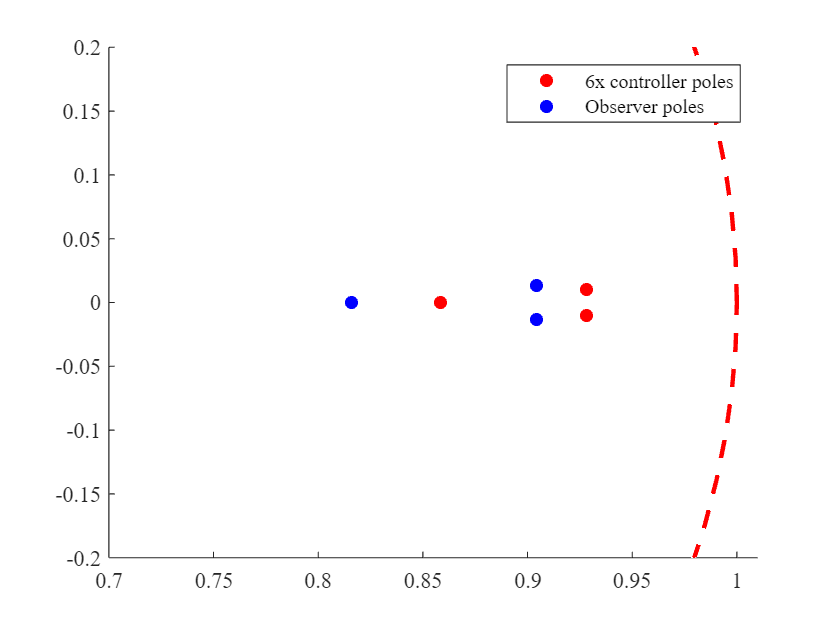



scatter(real(discretePoles.^6),imag(discretePoles.^6),"red","filled")
hold on
scatter(real(desiredPoles),imag(desiredPoles),"blue","filled")
viscircles([0 0], 1,'LineStyle','--');
hold off
legend("6x controller poles","Observer poles")
xlim([0.7 1.01])
ylim([-0.2 0.2])